# 3 DOF 腿部运动学动力学建模

## 1 坐标系建立

在 Simulink 中本身存在一个世界坐标系，记作 ${W}$。倘若我们将腿部的基坐标系的各个方向均设置与 $W
$ 相同，我们在分析左右腿的时候就会发现两条腿的正运动学方程竟然是不一样的。为了运动学的统一性，我们按以下方式建立腿部基坐标系:

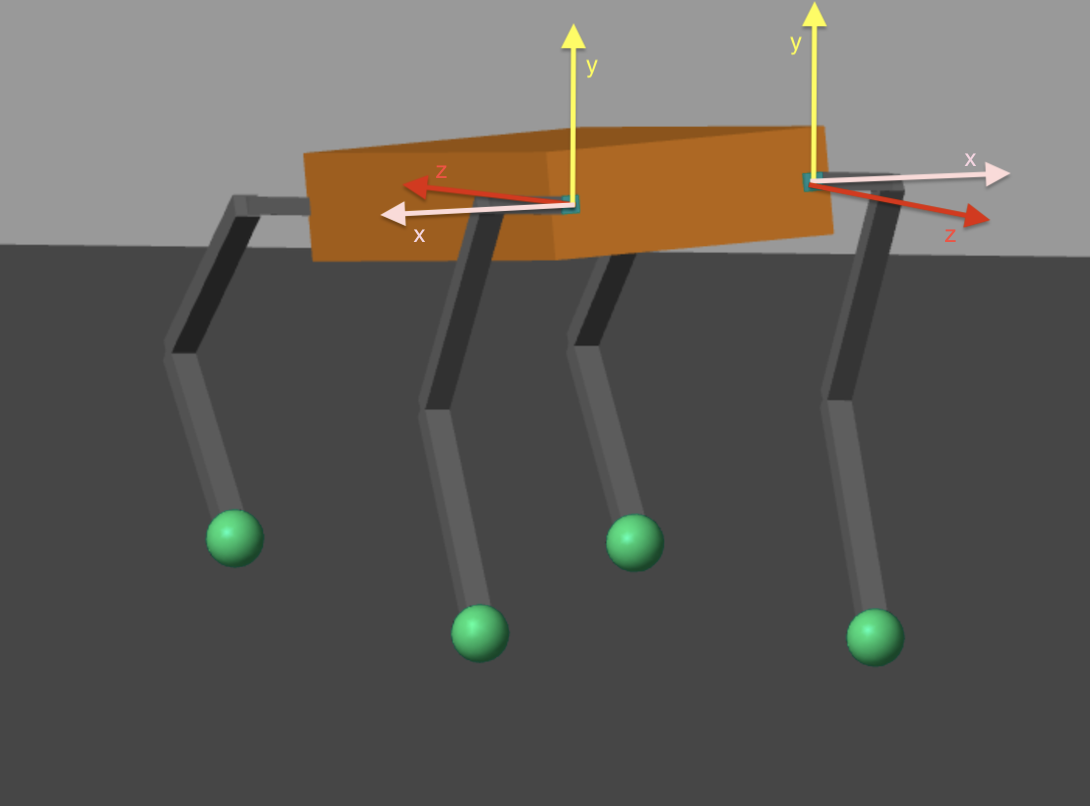

可以看出左右腿的基坐标系相对于世界坐标系之间存在一个 180 度的旋转。

## 2 参数定义

$l_1$：髋关节连杆长度(m)

$l_2$：大腿连杆长度

$l_3$：小腿连杆长度

$t_1
$：髋关节转角

$t_2$：大腿关节转角

$t_3$：小腿关节转角

Leg = struct;

g = sym("g");

Leg.l1 = sym("l1");
Leg.l2 = sym("l2");
Leg.l3 = sym("l3");
Leg.t1 = sym("t1");
Leg.t2 = sym("t2");
Leg.t3 = sym("t3");

## 3 运动学推导

### 3.1 正运动学

% 建立三个关节之间的变换矩阵
Leg.T_01 = [cos(Leg.t1) -sin(Leg.t1) 0 0;
            sin(Leg.t1) cos(Leg.t1) 0 0;
            0 0 1 0;
            0 0 0 1];
Leg.T_12 = [1 0 0 Leg.l1;
        0 cos(Leg.t2) -sin(Leg.t2) 0;
        0 sin(Leg.t2) cos(Leg.t2) 0;
        0 0 0 1];
Leg.T_23 = [1 0 0 0;
        0 cos(Leg.t3) -sin(Leg.t3) -Leg.l2;
        0 sin(Leg.t3) cos(Leg.t3) 0;
        0 0 0 1];

% 计算足段点在基坐标系中的位置
Leg.T_03 = Leg.T_01 * Leg.T_12 * Leg.T_23;
Leg.P_thigh = [0;-Leg.l3;0];
Leg.P_t = [Leg.P_thigh;1];
Leg.P_ans = Leg.T_03 * Leg.P_t;
Leg.P_ans = simplify(Leg.P_ans(1:3,:));

### 3.2 逆运动学

Leg.x = sym("x");
Leg.y = sym("y");
Leg.z = sym("z");
Leg.P_fb = [Leg.x,Leg.y,Leg.z];
Leg.L = sqrt(abs(Leg.x^2 + Leg.y^2 - Leg.l1^2));
Leg.t1i = atan2((Leg.y * Leg.l1 + Leg.x * Leg.L),(Leg.x * Leg.l1 - Leg.y * Leg.L));
Leg.t3i = pi - acos((Leg.l2^2 + Leg.l3^2 - (Leg.x^2 + Leg.y^2 + Leg.z^2 - Leg.l1^2))/(2*Leg.l2*Leg.l3));
Leg.t2i = -(Leg.z + (Leg.l3*(Leg.y - (Leg.l1*(imag(Leg.l1*Leg.x) + real(Leg.l1*Leg.y) - imag(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) ...
    + real(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2))))/abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) + Leg.l1*Leg.y*1i ...
    + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i))*(1 - (Leg.l1^2 + Leg.l2^2 + Leg.l3^2 - Leg.x^2 - Leg.y^2 - Leg.z^2)^2/(4*Leg.l2^2*Leg.l3^2))^(1/2))/((Leg.l2*(imag(Leg.l1*Leg.y) ...
    - real(Leg.l1*Leg.x) + imag(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) + real(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2))))/abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) ...
    + Leg.l1*Leg.y*1i + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i) - ((imag(Leg.l1*Leg.y) - real(Leg.l1*Leg.x) + imag(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) + real(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)))*(Leg.l1^2 + Leg.l2^2 + Leg.l3^2 - Leg.x^2 - Leg.y^2 - Leg.z^2))/(2*Leg.l2*abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) + Leg.l1*Leg.y*1i + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i))))/(Leg.l2 - Leg.l3*((Leg.l1^2 + Leg.l2^2 + Leg.l3^2 - Leg.x^2 - Leg.y^2 - Leg.z^2)/(2*Leg.l2*Leg.l3) ...
    + (Leg.l3*((Leg.l1^2 + Leg.l2^2 + Leg.l3^2 - Leg.x^2 - Leg.y^2 - Leg.z^2)^2/(4*Leg.l2^2*Leg.l3^2) - 1)*(imag(Leg.l1*Leg.y) - real(Leg.l1*Leg.x) + imag(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) + real(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2))))/(abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) + Leg.l1*Leg.y*1i + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i)*((Leg.l2*(imag(Leg.l1*Leg.y) - real(Leg.l1*Leg.x) + imag(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) + real(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2))))/abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) + ...
    Leg.l1*Leg.y*1i + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i) - ((imag(Leg.l1*Leg.y) - real(Leg.l1*Leg.x) + imag(Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)) + real(Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)))*(Leg.l1^2 + Leg.l2^2 + Leg.l3^2 - Leg.x^2 - Leg.y^2 - Leg.z^2))/(2*Leg.l2*abs(Leg.l1*Leg.x - Leg.y*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2) + Leg.l1*Leg.y*1i + Leg.x*(- Leg.l1^2 + Leg.x^2 + Leg.y^2)^(1/2)*1i))))));
Leg.t2i = asin(Leg.t2i);
Leg.q_des = [Leg.t1i;Leg.t2i;Leg.t3i];

## 4 动力学推导

在本项目中，运动学的用处是将 MPC 解算出的足端给地面施加的作用力转化为腿上各个关节的扭矩。

% 需要先求出腿部的雅可比矩阵
% 通过前面的正运动学对时间求导得到
Leg.J = [Leg.l2*cos(Leg.t1)*cos(Leg.t2) - Leg.l1*sin(Leg.t1) - Leg.l3*(cos(Leg.t1)*sin(Leg.t2)*sin(Leg.t3) - cos(Leg.t1)*cos(Leg.t2)*cos(Leg.t3)), - Leg.l3*(cos(Leg.t2)*sin(Leg.t1)*sin(Leg.t3) + cos(Leg.t3)*sin(Leg.t1)*sin(Leg.t2)) - Leg.l2*sin(Leg.t1)*sin(Leg.t2), -Leg.l3*(cos(Leg.t2)*sin(Leg.t1)*sin(Leg.t3) + cos(Leg.t3)*sin(Leg.t1)*sin(Leg.t2));
Leg.l1*cos(Leg.t1) - Leg.l3*(sin(Leg.t1)*sin(Leg.t2)*sin(Leg.t3) - cos(Leg.t2)*cos(Leg.t3)*sin(Leg.t1)) + Leg.l2*cos(Leg.t2)*sin(Leg.t1),   Leg.l3*(cos(Leg.t1)*cos(Leg.t2)*sin(Leg.t3) + cos(Leg.t1)*cos(Leg.t3)*sin(Leg.t2)) + Leg.l2*cos(Leg.t1)*sin(Leg.t2),  Leg.l3*(cos(Leg.t1)*cos(Leg.t2)*sin(Leg.t3) + cos(Leg.t1)*cos(Leg.t3)*sin(Leg.t2));
                                                                                       0,                                                - Leg.l3*cos(Leg.t2 + Leg.t3) - Leg.l2*cos(Leg.t2),                                        -Leg.l3*cos(Leg.t2 + Leg.t3)];


$$\tau = -J^\top F'$$


Leg.fx = sym("fx");
Leg.fy = sym("fy");
Leg.fz = sym("fz");
Leg.GRF = [Leg.fx;Leg.fy;Leg.fz];
Leg.torques = - Leg.J.' * Leg.GRF;